CheetahVideo = VideoReader("Cheetah.mp4")

CheetahVideo =   VideoReader with properties:

   General Properties:
            Name: 'Cheetah.mp4'
            Path: 'C:\Users\21692\Desktop\Etudes en France\IMT\FISEA2\Computer Vision\Project\Cheetah'
        Duration: 9.6000
     CurrentTime: 0
       NumFrames: 230

   Video Properties:
           Width: 640
          Height: 360
       FrameRate: 23.9760
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


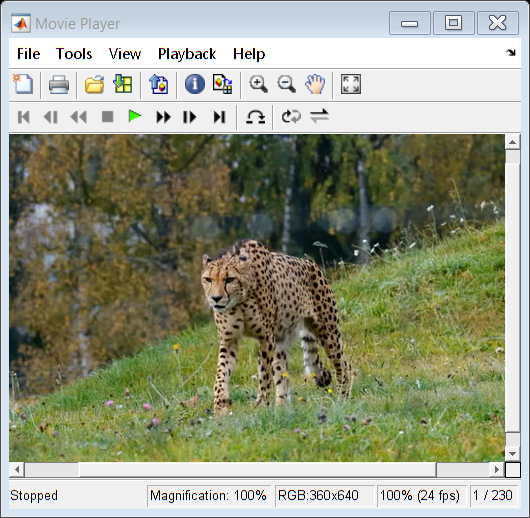

implay("Cheetah.mp4")

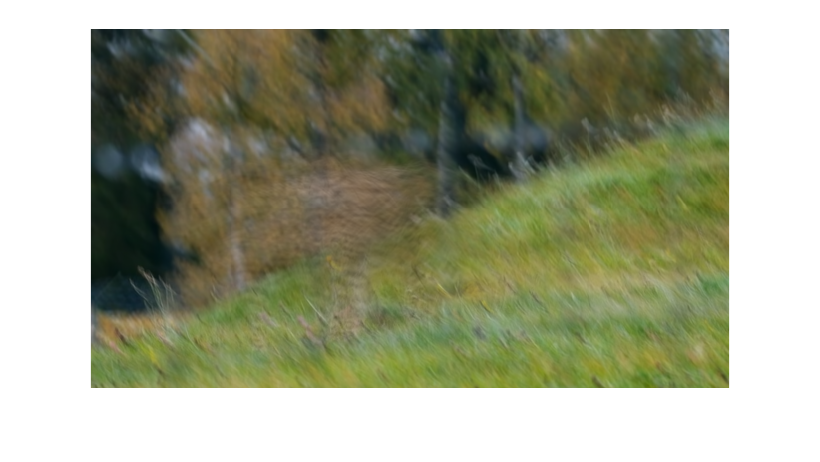

numFrames_Cheetah= CheetahVideo.NumFrames;
avg_bg = im2double(read(CheetahVideo,1));
for i = 2: numFrames_Cheetah
    avg_bg = avg_bg+im2double(read(CheetahVideo,i));
end
avg_bg = avg_bg /numFrames_Cheetah;
imshow(avg_bg)

numFrames_Cheetah= CheetahVideo.NumFrames;
v_seg= VideoWriter("Boxed_Cheetah","MPEG-4");

v_seg.FrameRate = CheetahVideo.FrameRate;
v_seg_comb.FrameRate = CheetahVideo.FrameRate;
%open(v_seg);
bboxes = [];
idxes = [];
for i = 1 : numFrames_Cheetah
    frame = read(CheetahVideo,i);
    idx = string(i);
    %while strlength(idx) ~= 3
    %    idx = append("0",idx);
    %end
    %imwrite(frame,"Cheetah-"+idx+".png");
    [BW,maskedImage] = segmentImageCheetah(abs(im2double(frame) - avg_bg));
    BW = filterRegionsChettah(BW);
    props = regionprops("table",BW,"BoundingBox");
    BoxedCheetah =insertShape(frame,"Rectangle",props.BoundingBox,"LineWidth",3,"Color","yellow");
    %writeVideo(v_seg, BoxedCheetah );
    bboxes = [bboxes;props];
    idxes = [idxes;i];

end
%close(v_seg);

coords=[];
coords.frames= idxes;
coords.x1 = bboxes.BoundingBox(:,1);
coords.y1 = bboxes.BoundingBox(:,2);
coords.w = bboxes.BoundingBox(:,3);
coords.h = bboxes.BoundingBox(:,4);

coords = struct2table(coords);
writetable(coords,"coords.txt");

implay("Boxed_Jellyfish.mp4")

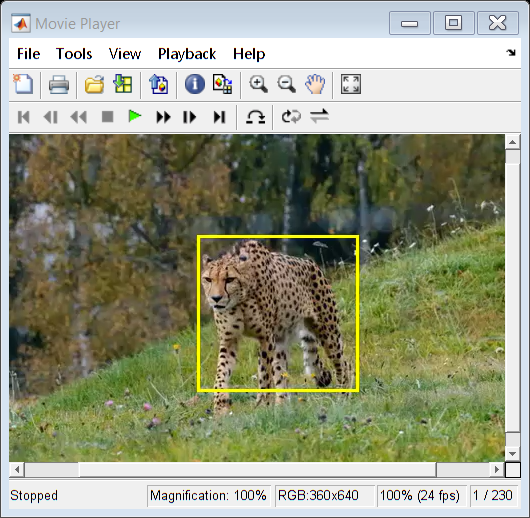

implay("Boxed_Cheetah.mp4")